# Pre Lab 1

Bar Yerushalmian

Ben Efrath

## Q1

% a) Double zero matrix
m1 = zeros(5,5,"double")

m1 =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



% b) Double matrix with 0.134
m2 = zeros(5,5,"double")+double(0.134)

m2 =     0.1340    0.1340    0.1340    0.1340    0.1340
    0.1340    0.1340    0.1340    0.1340    0.1340
    0.1340    0.1340    0.1340    0.1340    0.1340
    0.1340    0.1340    0.1340    0.1340    0.1340
    0.1340    0.1340    0.1340    0.1340    0.1340



% c) Double matrix with random values [-1.5, 3.4]
% Given range [a,b] the formula: m = a + (b-a).*rand([5,5])
m3 = -1.5 + (3.4 + 1.5).*rand([5,5],"double")

m3 =     0.2231   -0.0994   -1.1283   -0.8635   -0.7053
    2.5711    2.2103   -1.2356    1.2872    2.3920
    1.3678    2.1933    1.1009    0.8000    0.0250
    1.1936    0.3642    2.3179   -1.4417    1.0898
    2.9942    1.2823    3.0767    0.1519   -0.6883



% d) Make m3 into uint8 with casting.
% All the negative numbers turned to 0. All fractions were rounded to the
% closest integer. Becasue it's unsigned, it did meet our expectations.
m3 = uint8(m3)

m3 = 5×5 uint8 matrix
   0   0   0   0   0
   3   2   0   1   2
   1   2   1   1   0
   1   0   2   0   1
   3   1   3   0   0



% e) Make 5x5 matrix using uint8 in range of [0,250]
A = uint8(250.*rand([5,5]))

A = 5×5 uint8 matrix
   150   113   206    27   217
    66    21   135   240    21
   164    57   249     1   100
   172   228    20   194    65
   187    38   111   204   200



% f) 
% All The values above 127 are now 255.
A = A.*2

A = 5×5 uint8 matrix
   255   226   255    54   255
   132    42   255   255    42
   255   114   255     2   200
   255   255    40   255   130
   255    76   222   255   255



% g)
% Find the maximum value in the matrix using find().
v = max(A(:))           % value

v = uint8
255

[row,column] = find(A == v)

row =      1
     3
     4
     5
     4
     1
     2
     3
     2
     4


column =      1
     1
     1
     1
     2
     3
     3
     3
     4
     4


## Q2

% a)
% Create unit matrix I1.
I1=eye(3,4,"double")

I1 =      1     0     0     0
     0     1     0     0
     0     0     1     0



% b)
% Create row index matrix I2 and column index matrix I3.
x = 1:4;
y = 1:3;
[I3,I2] = meshgrid(x,y)

I3 =      1     2     3     4
     1     2     3     4
     1     2     3     4


I2 =      1     1     1     1
     2     2     2     2
     3     3     3     3



% c)
% Transform I3 matrix into a vector.
% The function sets the columns of the 
% matrix one after eachother to creare a vector.
I3a = reshape(I3,1,[])

I3a =      1     1     1     2     2     2     3     3     3     4     4     4



% d)
% We didnt get the same vector. This Vector is like reshape of I2.
% Because we transposed I3 it became I2
% Now it's like the rows are set one after eachother to create a vector.
I3b = reshape(I3.',1,[])

I3b =      1     2     3     4     1     2     3     4     1     2     3     4



% e)
% the vector I3c is similar to the vector I3a.
% we can say that reshape makes a column vector from the matrix and than
% transpose it.
I3c = I3(:).'

I3c =      1     1     1     2     2     2     3     3     3     4     4     4


## Q3

% repmat Is copying the matrix 3 times in the x axes and 2 times in the y
% axes.
A1 = repmat(A,3,4)

A1 = 15×20 uint8 matrix
   255   226   255    54   255   255   226   255    54   255   255   226   255    54   255   255   226   255    54   255
   132    42   255   255    42   132    42   255   255    42   132    42   255   255    42   132    42   255   255    42
   255   114   255     2   200   255   114   255     2   200   255   114   255     2   200   255   114   255     2   200
   255   255    40   255   130   255   255    40   255   130   255   255    40   255   130   255   255    40   255   130
   255    76   222   255   255   255    76   222   255   255   255    76   222   255   255   255    76   222   255   255
   255   226   255    54   255   255   226   255    54   255   255   226   255    54   255   255   226   255    54   255
   132    42   255   255    42   132    42   255   255    42   132    42   255   255    42   132    42   255   255    42
   255   114   255     2   200   255   114   255     2   200   255   114   255     2   200   255   114   255     2   200
   255  

## Q4

% flipud flips the matrix upside down.
A=flipud(A)

A = 5×5 uint8 matrix
   255    76   222   255   255
   255   255    40   255   130
   255   114   255     2   200
   132    42   255   255    42
   255   226   255    54   255


## Q5

% 1st Ex
A1 = [ 1 2 3 4 ]

A1 =      1     2     3     4



B1_pre = padarray(A1,3,9,'pre')

B1_pre =      9     9     9     9
     9     9     9     9
     9     9     9     9
     1     2     3     4



% 2nd Ex
A2 = [ 1 2; 3 4 ]

A2 =      1     2
     3     4



B2_post = padarray(A2,[3 2],'replicate','post')

B2_post =      1     2     2     2
     3     4     4     4
     3     4     4     4
     3     4     4     4
     3     4     4     4



% 1st one with 'post' and 'both'

B1_post = padarray(A1,3,9,'post')

B1_post =      1     2     3     4
     9     9     9     9
     9     9     9     9
     9     9     9     9



B1_both = padarray(A1,3,9,'both')

B1_both =      9     9     9     9
     9     9     9     9
     9     9     9     9
     1     2     3     4
     9     9     9     9
     9     9     9     9
     9     9     9     9



% 2nd one with 'both' and 'circular'

B2_both = padarray(A2,[3 2],'circular','both')

B2_both =      3     4     3     4     3     4
     1     2     1     2     1     2
     3     4     3     4     3     4
     1     2     1     2     1     2
     3     4     3     4     3     4
     1     2     1     2     1     2
     3     4     3     4     3     4
     1     2     1     2     1     2



% padarray is taking an array and padding it with a given number or a
% series of numbers. It's done with additional collums or rows. There is an
% option to choose where to pad it.

## Q6

% imshow show the matrix as an image where every number in the matrix
% represent a level of gray, the square brackets are the range for the gray level.
% it means that 10 is black and 20 is white.
I = uint8(20.*rand([3,5]))

I = 3×5 uint8 matrix
    9    5   17    3    7
   18    3   12   17   10
    4    3   11   12    8


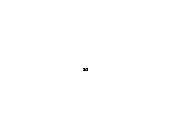

imshow(I ,[10 20])

## Q7

I=imread("logoruppin.jpg")

I = 217×217×3 uint8 array
I(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255  

I1=rgb2gray(I)

I1 = 217×217 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   25

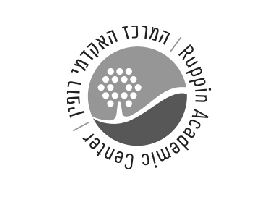

imshow(I1)

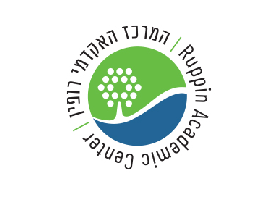

imshow(I)

## Q8

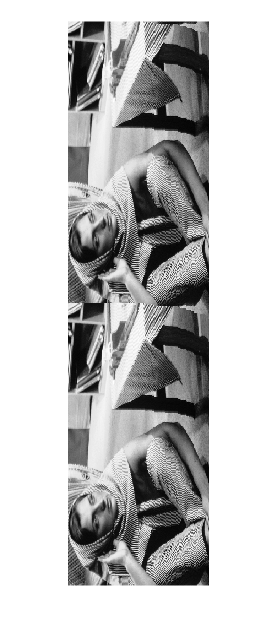

%In order to use this function we need the path to the file, the file name
%and size for X and Y.
% fread reads binary data from a file in uint8 format.

FilePath = "D:\ImageProc\lab 1";
FileName = "barbara_gray.raw";
Img1 = ImgLoad(FilePath,FileName,1024,256);
imshow(mat2gray(Img1));

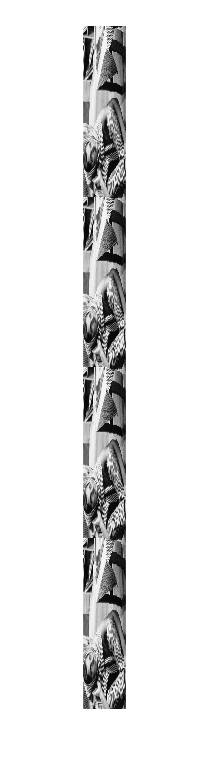


Img2 = ImgLoad(FilePath,FileName,2048,128);
imshow(mat2gray(Img2));

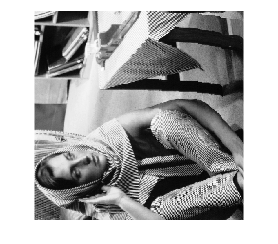


Img3 = ImgLoad(FilePath,FileName,512,512);
imshow(mat2gray(Img3));


% 512X512 is the correct size, no duplications.

## Q9

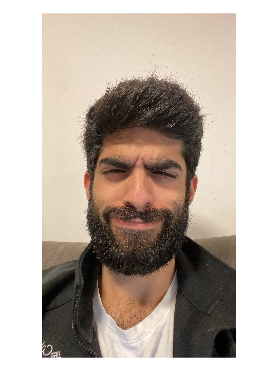

Bar = imread("Bar.jpg");
BarPicSize = size(Bar);
imshow(Bar);

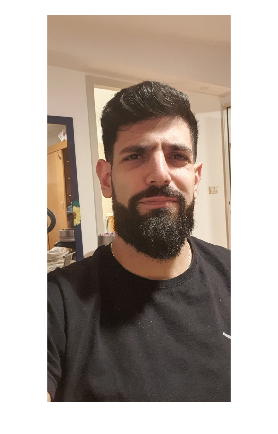


Ben = imread("Ben.jpg");
BenPicSize = size(Ben);
imshow(Ben);